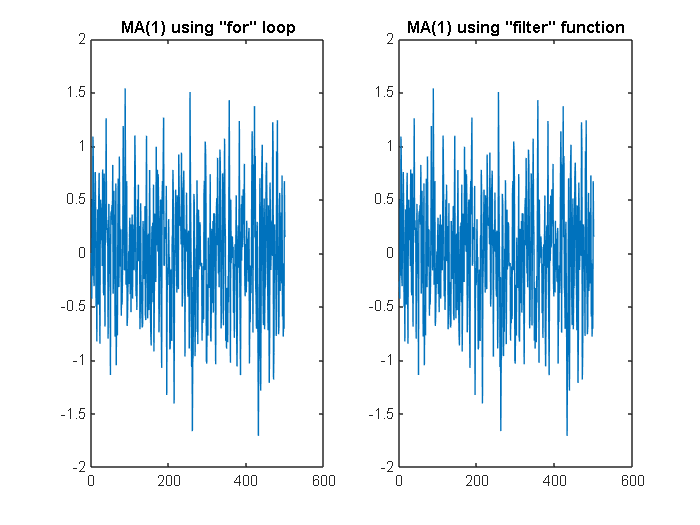

% EXERCISE 3
T=500;   % numebr of observation
tht=.3;  % value of theta 
e=randn(T,1)*sqrt(.3);  % white noise process 
x = zeros(T, 1);  % Preallocate x to hold T observations
% using for 
for t=2:T
    x(t)=tht*e(t-1)+e(t);
end
% using filter
y=filter([1,tht],1,e);

% plot of the results 
subplot(1,2,1)
plot(x)
title('MA(1) using "for" loop')
subplot(1,2,2)
plot(y)
title('MA(1) using "filter" function')